# ***Linear Control System Lab***

# ***MohammadParsa Dini - 400101204***

# *CHW2*

## *Assignment N.O. 2*

***Section 1 (*****System Identification and Control*****): ***

**Initial Code:**

clc; clear; close all;

**Part a)**

u0 = 0.2; % OP for input
y0 = 0.5; % OP for output

% Linearize sqrt(u) around u0
sqrt_u0 = sqrt(u0);
dsqrt_du = 1 / (2 * sqrt_u0); 

% 20y_dot + 4y = 4.5*sqrt(u)
a = -4 / 20; % Coefficient for y
b = (4.5 * dsqrt_du) / 20; % Coefficient for u

% Linearized tf
G_a = tf(b, [1, -a]); % TF: b / (s - a)
disp('Linearized Transfer Function (a):');

Linearized Transfer Function (a):


G_a

G_a =
 
  0.2516
  -------
  s + 0.2
 
Continuous-time transfer function.



**Part b)**

% Nonlinear system simulation
nonlinear_ode = @(t, y, u) -0.2 * y + 0.225 * sqrt(u);

% a small step input
u_step = @(t) 0.2 + (t >= 0) * 0.05; % Step input from 0.2 to 0.25
t_span = [0, 10]; % Time span for simulation
y0 = 0.5; % Initial output value
[t, y] = ode45(@(t, y) nonlinear_ode(t, y, u_step(t)), t_span, y0);

% time constant (tau) and gain (K) from step response
delta_y = y(end) - y0; % Steady-state change
K = delta_y / 0.05; % Gain (change in output / step size)

% time constant (time to reach 63.2% of total change)
y_target = y0 + 0.632 * delta_y; % 63.2% point
tau_index = find(y >= y_target, 1); % Find index where y crosses target
tau = t(tau_index); % Corresponding time is the time constant

% first-order transfer function
G_b = tf(K, [tau, 1]); % TF: K / (tau*s + 1)
disp('Derived First-Order Transfer Function (b):');

Derived First-Order Transfer Function (b):


G_b

G_b =
 
   1.081
  -------
  4 s + 1
 
Continuous-time transfer function.



**Part c)**

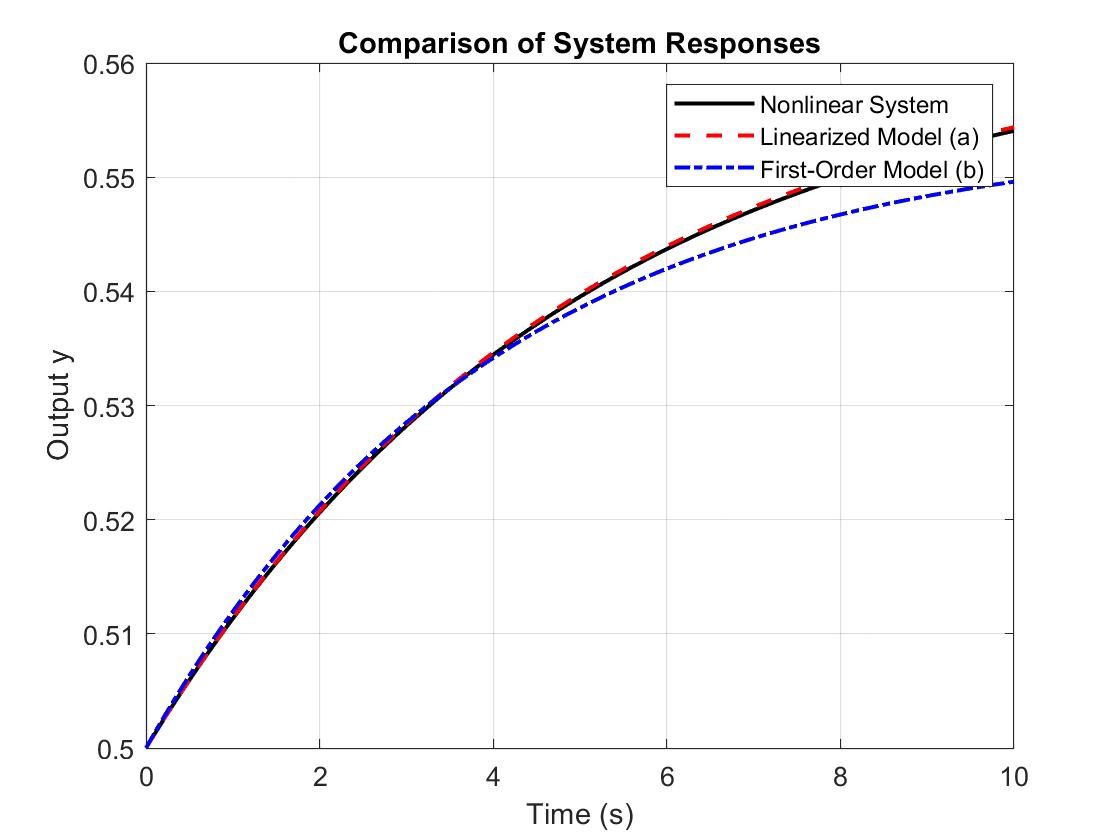

t = 0:0.01:10; 
u_step = 0.25 * ones(size(t)); % Step input from 0.2 to 0.25

y_nonlinear = zeros(size(t));
y_nonlinear(1) = y0;
for i = 2:length(t)
    dt = t(i) - t(i-1);
    y_nonlinear(i) = y_nonlinear(i-1) + ...
        dt * (-0.2 * y_nonlinear(i-1) + 0.225 * sqrt(u_step(i)));
end

% Linearized models
y_linear_a = lsim(G_a, u_step - 0.2, t) + y0 ; 
y_linear_b = lsim(G_b, u_step - 0.2, t) + y0; 

% comparison
figure;
plot(t, y_nonlinear, 'k-', 'LineWidth', 1.5); hold on;
plot(t, y_linear_a, 'r--', 'LineWidth', 1.5);
plot(t, y_linear_b, 'b-.', 'LineWidth', 1.5);
legend('Nonlinear System', 'Linearized Model (a)', 'First-Order Model (b)');
xlabel('Time (s)'); ylabel('Output y');
title('Comparison of System Responses');
grid on;

**Part d)**

**Note: Theoretical Calculations are attached.**

- **When **$U(s) = \frac{1}{s}$:

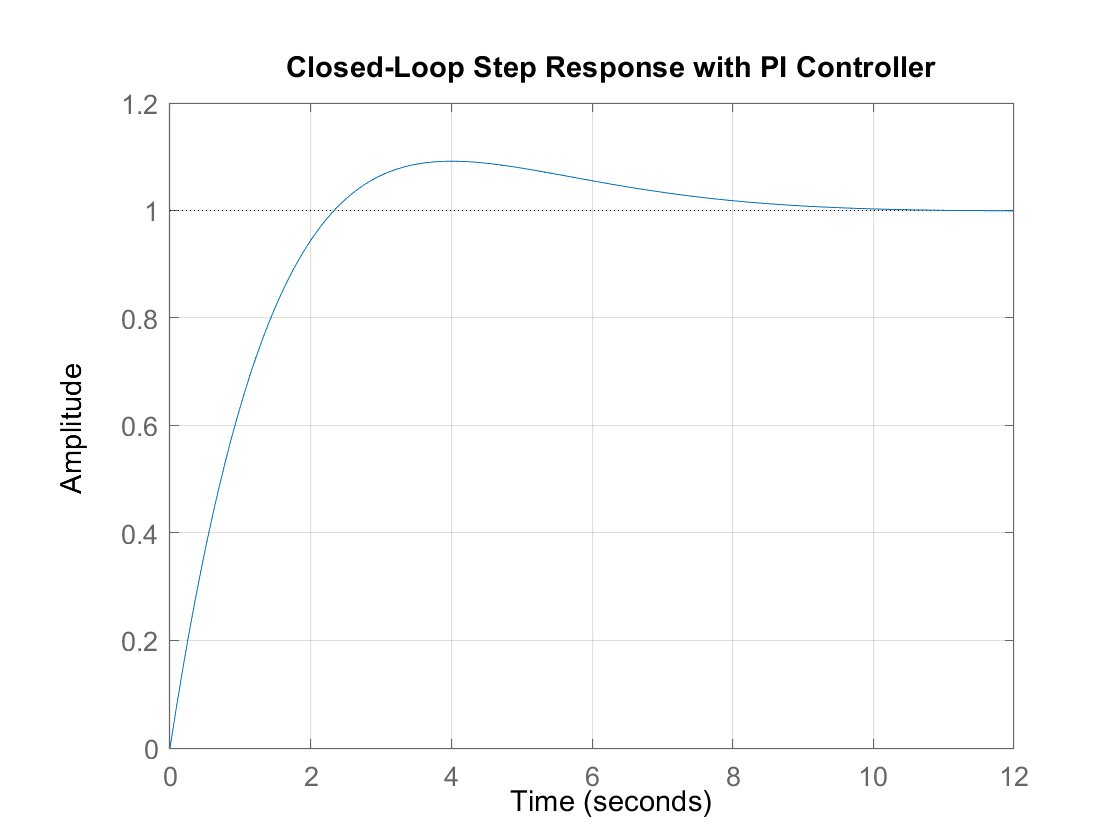

% PI controller
Kp = 3.4; % Proportional gain 
Ki = 1.6; % Integral gain (initial guess)

% tf
Gc = tf([Kp, Ki], [1, 0]);

G_open = G_a; % linearized model from part (a)

% Closed-loop tf
G_cl = feedback(Gc * G_open, 1);

figure;
step(G_cl);
title('Closed-Loop Step Response with PI Controller');
grid on;

% Performance metrics: 
overshoot = stepinfo(G_cl).Overshoot;
settling_time = stepinfo(G_cl).SettlingTime;

disp('PI Controller Performance:');

PI Controller Performance:


fprintf('Overshoot: %.2f%%\n', overshoot);

Overshoot: 9.17%


fprintf('Settling Time: %.2f seconds\n', settling_time);

Settling Time: 7.87 seconds


As you can see every criterion is met. Zero steady-state error in response to unit step input was shown theoretically.

2. **When u(t) and **$\Delta u$ are given:

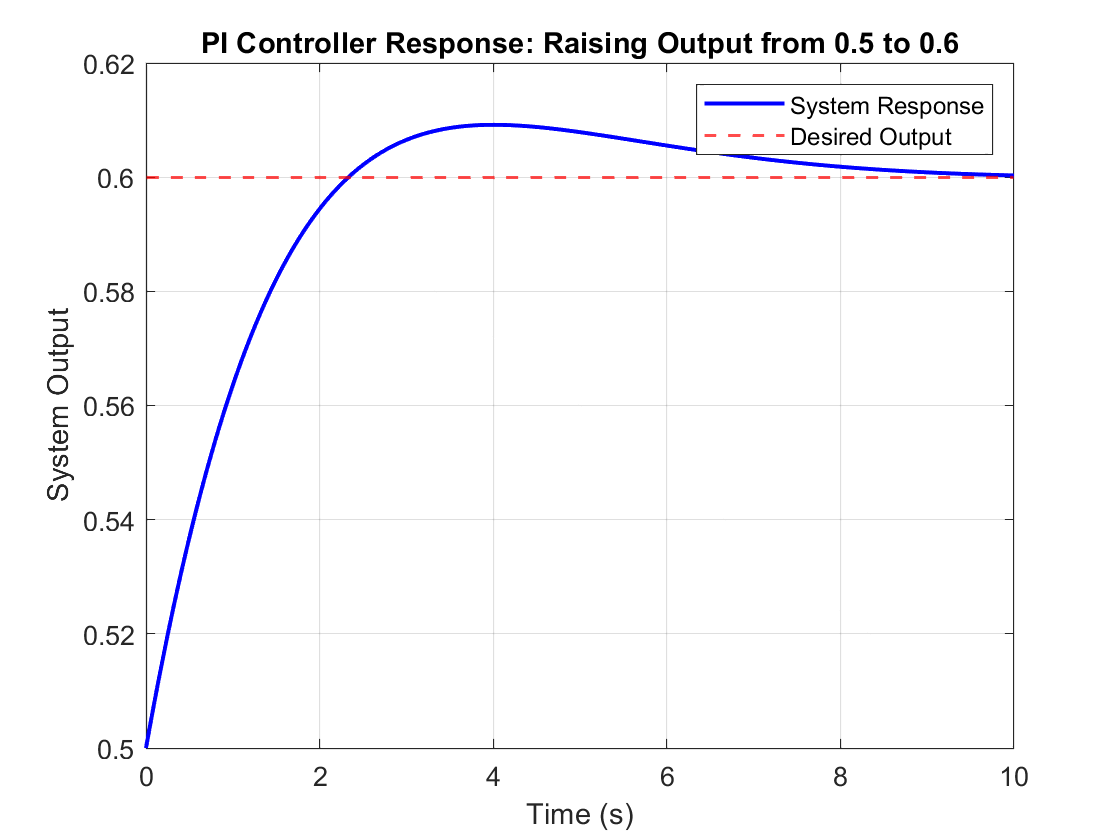

% OP and the desired output
initial_output = 0.5; % Initial steady-state output
desired_output = 0.6; % Desired steady-state output
step_magnitude = desired_output - initial_output; 

% Linearized system from part (a)
G_open = G_a; 

Kp = 3.4; % Proportional gain 
Ki = 1.6; % Integral gain 

% PI controller tf
Gc = tf([Kp, Ki], [1, 0]); 

% Closed-loop tf unity feedback
G_cl = feedback(Gc * G_open, 1); 

t = 0:0.01:10; 
step_input = step_magnitude * ones(size(t)); 
[output, t_response] = step(step_magnitude * G_cl, t);

figure;
plot(t_response, initial_output + output, 'b-', 'LineWidth', 1.5); hold on;
yline(desired_output, 'r--', 'LineWidth', 1.2); 
xlabel('Time (s)');
ylabel('System Output');
title('PI Controller Response: Raising Output from 0.5 to 0.6');
legend('System Response', 'Desired Output');
grid on;

step_info = stepinfo(G_cl);
disp('PI Controller Performance:');

PI Controller Performance:


fprintf('Overshoot: %.2f%%\n', step_info.Overshoot);

Overshoot: 9.17%


fprintf('Settling Time: %.2f seconds\n', step_info.SettlingTime);

Settling Time: 7.87 seconds


As you can see every criterion is met. Zero steady-state error in response to unit step input was shown theoretically.

***Section 2 (*****Controller Design & Actuator Dynamic*****): ***

**Initial Code:**

clc; clear; close all;

**Part b)**

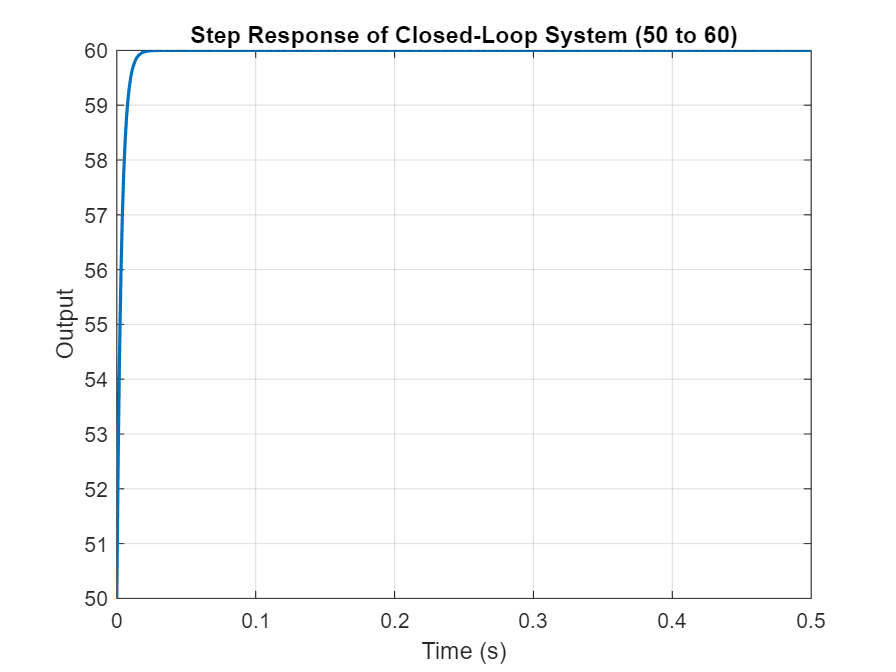

%% Part (b): Design and Performance Assessment
clc; clear; close all;

num_G = 1.5; 
den_G = [0.5 1]; 
G = tf(num_G, den_G); % Tf G(s)

Kp = 100; % Proportional gain
Ki = 200; % Integral gain

% PI Controller tf
num_C = [Kp Ki]; 
den_C = [1 0]; 
C = tf(num_C, den_C);

% Closed-loop system tf
T = feedback(C*G, 1); 

% Performance assessment for step input (from 50 to 60)
step_magnitude = 10; 
initial_value = 50; 
final_value = 60; 
t = 0:0.001:0.5; 
[y, t_out] = step(step_magnitude * T + initial_value, t); % Step response

figure;
plot(t_out, y, 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Step Response of Closed-Loop System (50 to 60)');
% Analyze performance
info = stepinfo(T);
ss_error = abs(final_value - y(end));


fprintf('Performance Metrics:\n');
fprintf('Settling Time: %.4f seconds\n', info.SettlingTime);
fprintf('Overshoot: %.2f%%\n', info.Overshoot);
fprintf('Steady-State Error: %.4f\n', ss_error);

Performance Metrics:


As you can see every criterion is met. Zero steady-state error in response to unit step input was shown theoretically.

**Part c)**

% Actuator tf: A(s) = 0.99 / (0.1s + a)

Settling Time: 0.0130 seconds


a_values = [1, 2, 5, 10, 14.3, 15]; % Values of a

Overshoot: 0.00%


Steady-State Error: 0.0000



Performance Metrics with a = 1:


Settling Time: 0.7623 seconds


Overshoot: 74.86%


Steady-State Error: 0.2737


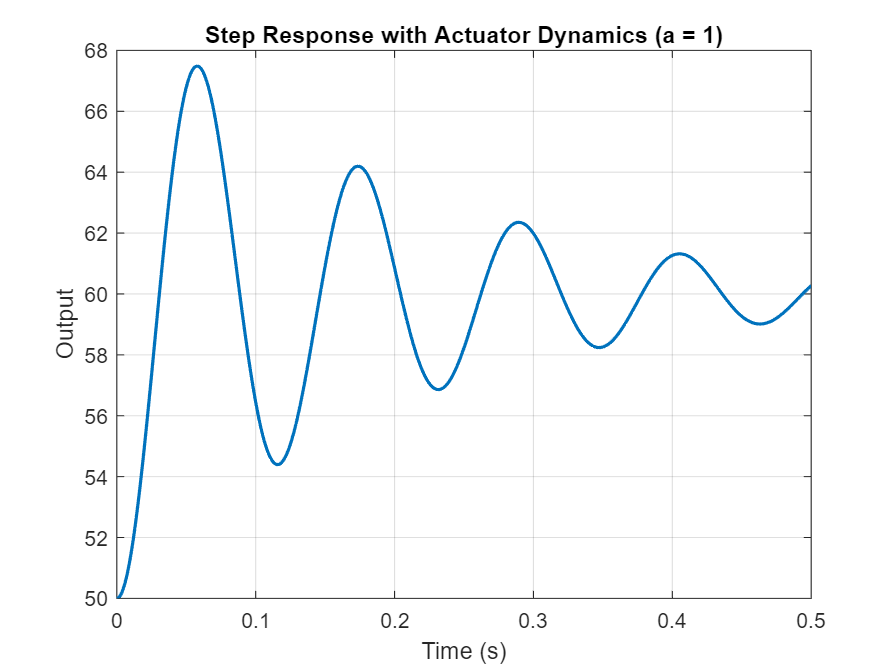


Performance Metrics with a = 2:


Settling Time: 0.3679 seconds


Overshoot: 55.51%


Steady-State Error: 0.0070


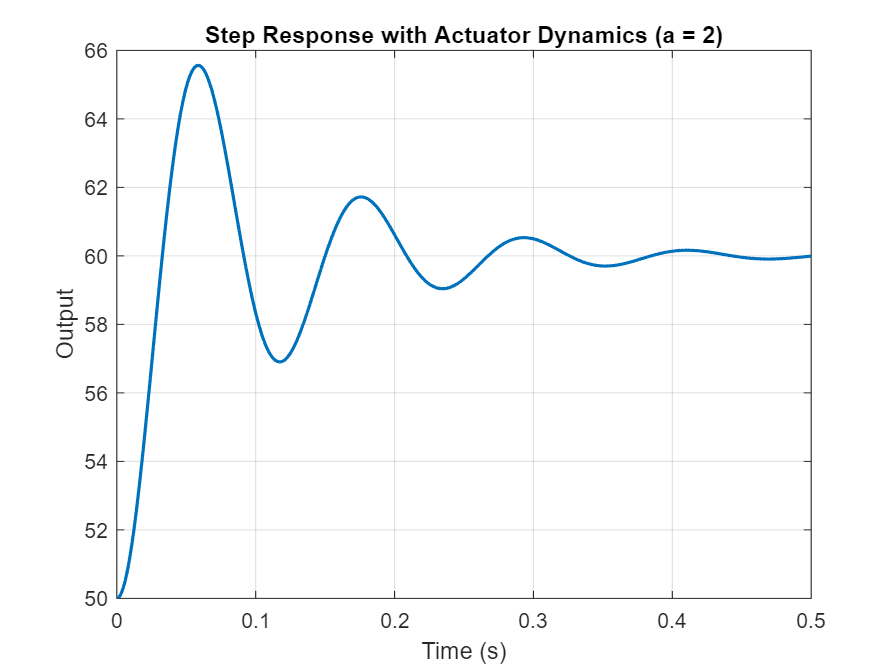


Performance Metrics with a = 5:


Settling Time: 0.1526 seconds


Overshoot: 19.75%


Steady-State Error: 0.0000


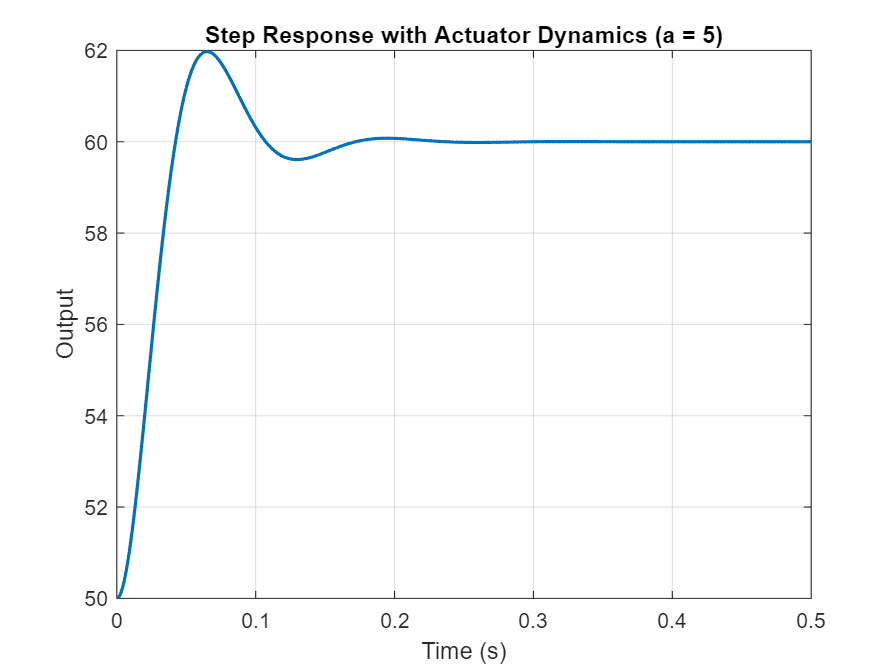


Performance Metrics with a = 10:


Settling Time: 0.0898 seconds


Overshoot: 0.07%


Steady-State Error: 0.0000


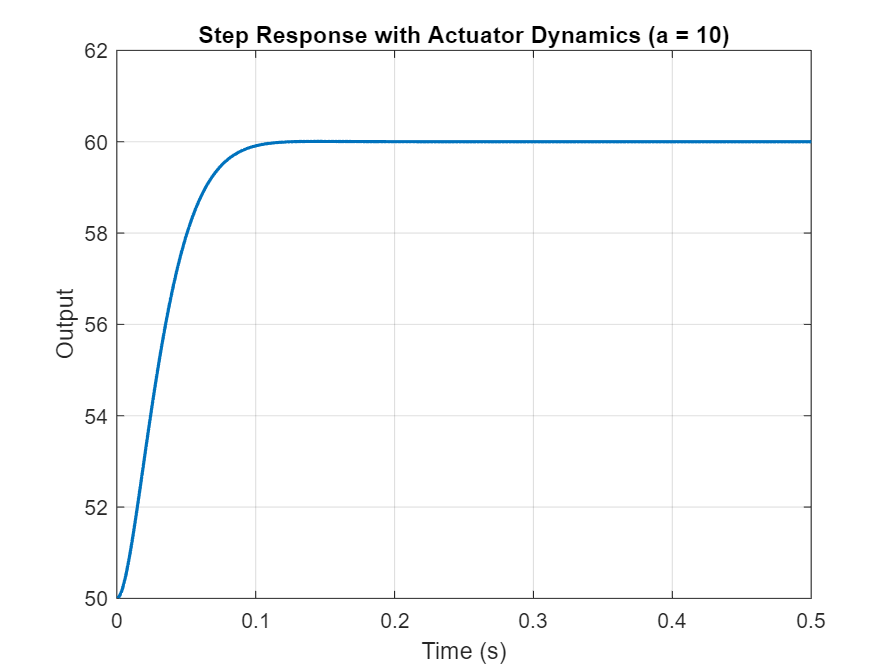


Performance Metrics with a = 1.430000e+01:


Settling Time: 0.1647 seconds


Overshoot: 0.00%


Steady-State Error: 0.0000


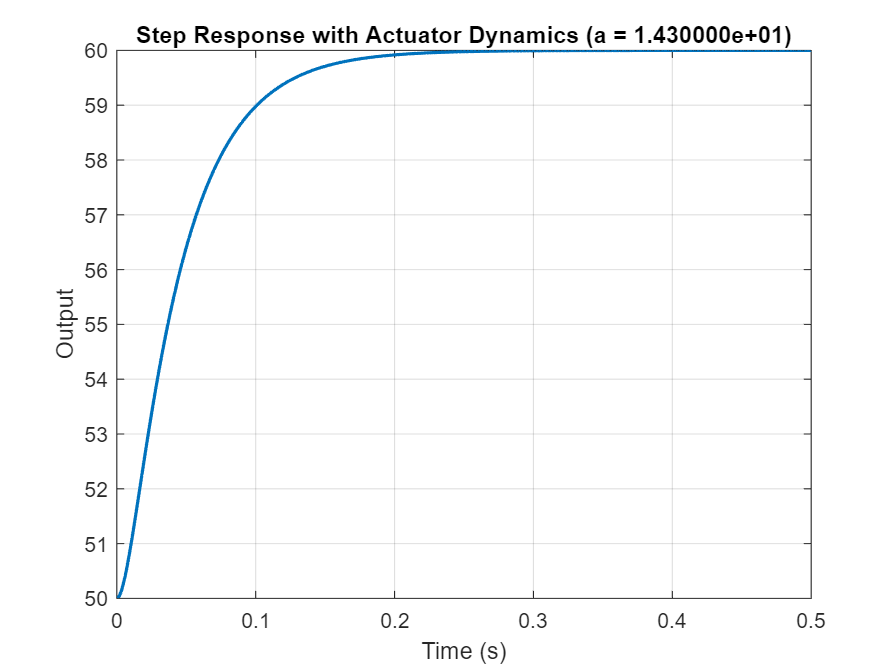


Performance Metrics with a = 15:


Settling Time: 0.1754 seconds


Overshoot: 0.00%


Steady-State Error: 0.0001


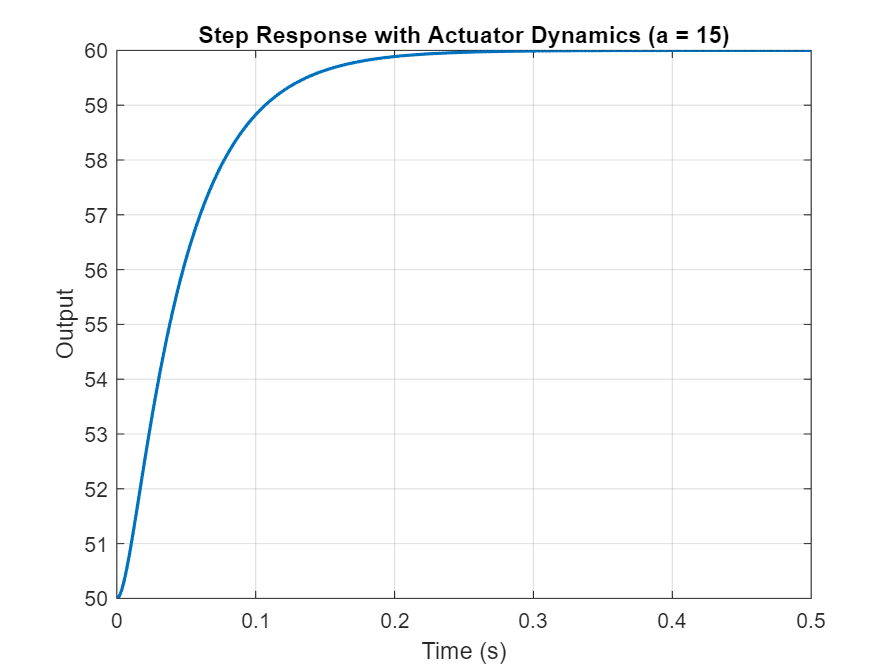

for i = 1:length(a_values)
    a = a_values(i);
    A = tf(0.99, [0.1 a]); 

    % Combined open-loop system
    G_actuated = A * G;

    % Closed-loop tf with actuator
    T_actuated = feedback(C * G_actuated, 1);

    % Step response
    [y_act, t_act] = step(step_magnitude * T_actuated + initial_value, t);

    % Analyze performance
    info_act = stepinfo(T_actuated);
    ss_error_act = abs(final_value - y_act(end));

    % Display results
    fprintf('\nPerformance Metrics with a = %d:\n', a);
    fprintf('Settling Time: %.4f seconds\n', info_act.SettlingTime);
    fprintf('Overshoot: %.2f%%\n', info_act.Overshoot);
    fprintf('Steady-State Error: %.4f\n', ss_error_act);

    % Plot step response
    figure;
    plot(t_act, y_act, 'LineWidth', 1.5);
    grid on;
    xlabel('Time (s)');
    ylabel('Output');
    title(sprintf('Step Response with Actuator Dynamics (a = %d)', a));
end

**Observations:**

**1. Settling Time**: As a increases, the settling time decreases significantly. For example: 

- a = 1: Settling time = 0.7623 seconds.

- a = 10: Settling time = 0.0898 seconds.

- a = 15: Settling time increases slightly to 0.1754 seconds.

This indicates that increasing aa improves the system's response speed, but there is a trade-off at higher values of a where the improvement is less pronounced.

**2. Overshoot**: The overshoot reduces as a increases: 

- a = 1: Overshoot = 74.86%.

- a = 5: Overshoot = 19.75%.

- $a \geq 10$: Overshoot becomes negligible (close to 0%).

This trend suggests that higher values of a stabilize the system and minimize oscillatory behavior.

**3.Steady-State Error**: For higher a, the steady-state error approaches zero, indicating improved tracking performance: 

- a = 1: Steady-state error = 0.2737.

- a = 5: Steady-state error = 0.0000.

- $a \geq 10$: The error remains negligible.

**4.System Dynamics**: The actuator dynamics, represented by $A(s) = \frac{0.99}{0.1s + a}$, play a significant role. As a increases, the pole of A(s) shifts further to the left in the s-plane, effectively speeding up the system response and improving stability.

**Findings:**

**Controller Design Adaptability**: Your controller works well across different values of a, demonstrating robustness to actuator dynamics.

**Trade-Offs**: While increasing a generally improves performance metrics, excessively high aa may result in marginal improvements and increased controller effort.

**Optimal Range**: Based on the metrics, a = 5 or a = 10 provides an optimal balance of fast response, low overshoot, and negligible steady-state error.